clc; clear; close all;

Problem 6.41

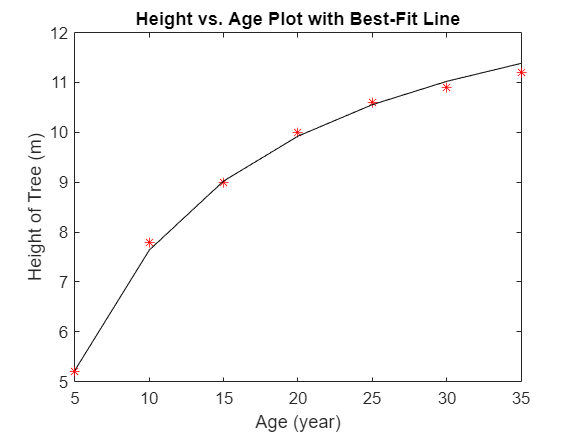

clear variables;
%The given data is initialized and plotted as asterisks here
Age = [5 10 15 20 25 30 35];
Height = [5.2 7.8 9 10 10.6 10.9 11.2];
h = plot(Age, Height,'r');
set(h,'Marker','*');
set(h,'LineStyle','none');
ylabel('Height of Tree (m)')
xlabel('Age (year)')
title('Height vs. Age Plot with Best-Fit Line')
hold on;

%y_bar is defined as 1/y
y_bar = 1./Height';
%M_mat is defined as column 1 == 1/x, and column 2 == 1
M_mat = horzcat((1./Age)', ones(length(Age),1));
%The coefficient matrix defined with pseudo-inverse
coeff_mat = M_mat \ y_bar;
%m is the reciprocal of the second coefficient as defined by the
%fit-function y=(mx)/(b+x)
m = 1/coeff_mat(2);
%b is the first coefficient multiplied by m
b = coeff_mat(1)*(1/coeff_mat(2));
%The fit values are calculated using the coefficients
y_fit = (m.*Age)./(b+Age);
%The least-squares best-fit is plotted on the same plot as data
fit_plt = plot(Age, y_fit,'k-');

Problem 6.42:

clear variables;
%Part a:

depth = [0 100 200 300 400 500 600 700 800 900 1100 1400 2000 3000];
salinity = [35.5 35.35 35.06 34.65 34.48 34.39 34.34 34.32 34.33 34.36 ...
    35.45 34.58 34.73 34.79];

%These are the x-values for part b
x=[250, 750, 1800];

%Pre-allocating some space for L_poly
L_poly = zeros(1);
%Implementing the general form for lagrange-polynomials (can take in a
%row-vector of values to evaluate at)
for x_val = 1:length(x)
    for inc1 = 1:length(depth)
        L_term = 1;
        for inc2 = 1:length(depth)
            if inc2 ~= inc1
                L_term = L_term.*(x(x_val)-depth(inc2))./(depth(inc1)-depth(inc2));
            end
        end
        L_poly(inc1) = L_term;
    end
    L_poly_vector(:,x_val) = L_poly;
end

%Part b:
y_int = zeros(length(x),1);
for interp = 1:length(x)
    y_int(interp) = sum(salinity.*L_poly_vector(:,interp)');
end

format shortG
%These are the interpolated values for part b
y_int(1) = sum(salinity.*L_poly_vector(:,1)')

y_int =        34.819
       34.321
      -2054.8



%Part c:
YI = interp1q(depth', salinity', [250, 750, 1800]')

YI =        34.855
       34.325
        34.68



%Part d:
% The results for my interpolation function break down for the depth of
% 1800 because the polynomial is a relatively high degree. The end behavior
% of the interpolated polynomial gives obviously incorrect values for the
% salinity. The interp1q function doesn't appear to have the same problem,
% as it gives a realistic number for the depth of 1800. The estimated salinity for
% 250ft and 750ft is very similar between the two approaches.

Problem 8.4

clear variables;
v = [12.5, 25, 37.5, 50, 62.5, 75];
d = [20, 59, 118, 197, 299, 420];
h = v(2) - v(1);  %Step size

%Part a:
dv_dt_2pt = (d(5)-d(4))/h

dv_dt_2pt =          8.16



dv_dt_3pt = (d(3) - 4*d(4) + 3*d(5)) / (2*h)

dv_dt_3pt =          9.08



%Part b:

stop_distance_2pt = d(5) + dv_dt_2pt * h

stop_distance_2pt =    401


stop_distance_3pt = d(5) + dv_dt_3pt * h

stop_distance_3pt =         412.5



%We see that the 3pt backwards estimate gives a closer estimation of the
%stopping distance based on the data, but it is still lower than the actual
%value for 75 mph

Problem 9.3

clear variables;
%Initializing data:

z = [0, 2, 4, 6, 8, 10, 12, 14, 16, 18, 20, 22, 24, 26, 28, 30, 32, 34, 36];
r = [10, 11, 11.9, 12.4, 13, 13.5, 13.8, 14.1, 13.6, 12.1, 8.9, 4.7, 4.1, 3.5, ...
    3.0, 2.4, 1.9, 1.2, 1.0];

%Part a:
h = z(2)-z(1);
SA_rect = 0;

%This is using the left-side of the interval to define the height of the
%rectangles, with intervals of h=2 because of the even division of the z.
for point = 2:length(r)
    SA_rect = SA_rect + h*r(point-1);
end
%Because surface area is 2pi*integral
SA_rect = 2*pi*SA_rect; 

%An alternative implementation for the rectangular method is: 
% SA_Rect = 2*pi*h*sum(r(1:end-1)

%This is following the alternative implementation template in the comment
%above, using the left-side as the height.
Vol_rect = pi*h*sum(r(1:end-1).^2);

disp('Composite rectangular method calculates surface area (cm^2):')

Composite rectangular method calculates surface area (cm^2):


disp(SA_rect)

         1949



disp('and volume (cm^3):')

and volume (cm^3):


disp(Vol_rect)

        10923




%Part b:

%This is the implementation of the constant-subinterval-width form (9.13 in
%textbook) of the composite trapezoid method
SA_trap = 2*pi * (h/2 * (r(1) + r(end)) + h*sum(r(2:end-1)));
Vol_trap = pi * (h/2 * (r(1)^2 + r(end)^2) + h*sum(r(2:end-1).^2));

disp('Composite trapezoid method calculates surface area (cm^2):')

Composite trapezoid method calculates surface area (cm^2):


disp(SA_trap)

       1892.5



disp('and volume (cm^3):')

and volume (cm^3):


disp(Vol_trap)

        10612




%Part c:

%This is the implementation of composite Simpson's 3/8 method (equal width
%version). Since there are 18 constant intervals, the 3/8 method is applicable.
SA_simp_int = 0;

%This loop is based on Eq. 9.21 and 9.22 in textbook
for inc = 2:length(r)-1
    if mod(inc,3) == 1
        SA_simp_int = SA_simp_int + r(inc)*2;
    else
        SA_simp_int = SA_simp_int + r(inc)*3;
    end
end
%This is the full value for the integral using the result of the loop and
%the start/end points of the function, with the 3/8 factor
SA_simp_int = (3*h/8) * (r(1) + r(end) + SA_simp_int);
SA_simp = 2*pi*SA_simp_int;

%This is the implementation for the volume:
Vol_simp_int = 0;
for inc = 2:length(r)-1
    if mod(inc,3) == 1
        Vol_simp_int = Vol_simp_int + r(inc)^2*2;
    else
        Vol_simp_int = Vol_simp_int + r(inc)^2*3;
    end
end
%Same thought process as for surface area above
Vol_simp_int = (3*h/8) * (r(1) + r(end) + Vol_simp_int);
Vol_simp = pi*Vol_simp_int;

disp('Composite Simpson''s 3/8 method calculates surface area (cm^2):')

Composite Simpson's 3/8 method calculates surface area (cm^2):


disp(SA_simp)

         1892



disp('and volume (cm^3):')

and volume (cm^3):


disp(Vol_simp)

        10398



Problem 10.1

clear variables;
%Part a:
h = 0.7;
x = 0:h:2.1;
y_eul = zeros(1);
y_eul(1) = 2;
deriv_func = @(a,b) (a.^2)./b;

%Calculating the true solution values here:
true_sol_func = @(a) ((2/3).*a.^3 + 4).^0.5;
y_true = true_sol_func(x);

disp('For x values of:')

For x values of:


disp(x)

            0          0.7          1.4          2.1



disp('The true values for y are:')

The true values for y are:


disp(y_true)

            2       2.0564       2.4144       3.1897




%Euler's explicit method:

for inc = 2:length(x)
    y_eul(inc) = y_eul(inc-1) + h*deriv_func(x(inc-1),y_eul(inc-1));
end

disp('Euler''s explicit method calculates:')

Euler's explicit method calculates:


disp(y_eul)

            2            2       2.1715       2.8033



disp('with error between the true and predicted solution at each point:')

with error between the true and predicted solution at each point:


disp(y_true - y_eul)

            0     0.056372       0.2429      0.38635




%Part b:
y_eul_mod = zeros(1);
y_eul_mod(1) = 2;

%Implementation of the Modified Euler's Method Algorithm (pg. 402)
for inc2 = 2:length(x)
    current_deriv = deriv_func(x(inc2-1),y_eul_mod(inc2-1));
    y_est = y_eul_mod(inc2-1) + h * current_deriv;
    y_est_deriv = deriv_func(x(inc2),y_est);
    y_eul_mod(inc2) = y_eul_mod(inc2-1) + 0.5 * (current_deriv + y_est_deriv) * h;
end

disp('The modified Euler''s method calculates:')

The modified Euler's method calculates:


disp(y_eul_mod)

            2       2.0857       2.4728         3.26



disp('with error between the true and predicted solution at each point:')

with error between the true and predicted solution at each point:


disp(y_true - y_eul_mod)

            0    -0.029378    -0.058435    -0.070379




%Part c:
y_rung = zeros(1);
y_rung(1) = 2;

%Calculating the weights k1->k4 for each pass of the 4th Order Runge-Kutta
%Then, calculates the next y-value based on the classical fourth-order
%Runge-Kutta weights
for inc3 = 2:length(x)
    k1 = deriv_func(x(inc3-1), y_rung(inc3-1));
    k2 = deriv_func(x(inc3-1) + h/2, y_rung(inc3-1) + 0.5*h*k1);
    k3 = deriv_func(x(inc3-1) + h/2, y_rung(inc3-1) + 0.5*h*k2);
    k4 = deriv_func(x(inc3), y_rung(inc3-1) + k3*h);
    y_rung(inc3) = y_rung(inc3-1) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);
end

disp('The classical fourth-order Runge-Kutta method calculates:')

The classical fourth-order Runge-Kutta method calculates:


disp(y_rung)

            2       2.0564       2.4147       3.1902



disp('with error between the true and predicted solution at each point:')

with error between the true and predicted solution at each point:


disp(y_true - y_rung)

            0  -4.9227e-05   -0.0002704  -0.00055593



Problem 6 (Custom Problem):

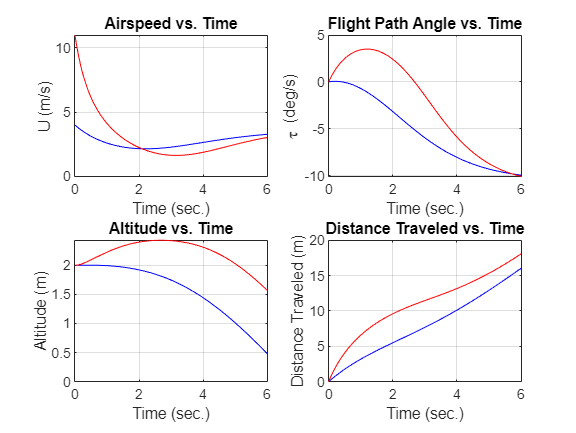

clear variables;
%This is where the ODE system is actually solved for both cases (Yout1 for
%first case, Yout2 for second case).
[Tout1, Yout1] = ode45(@airplane_deriv_func,[0,6],[4; 0; 2; 0]);
[Tout2,Yout2] = ode45(@airplane_deriv_func,[0,6],[11; 0; 2; 0]);

%plotting each of the value pairs now as subplots. Each plot's code is separated by a
%line of whitespace for readability. Blue is first case, red is second case
figure(1);
subplot(221);
plot(Tout1,Yout1(:,1),'b');
hold on;
grid on;
plot(Tout2,Yout2(:,1),'r');
title('Airspeed vs. Time')
xlabel('Time (sec.)')
ylabel('U (m/s)')

subplot(222);
plot(Tout1,Yout1(:,2),'b');
hold on;
grid on
plot(Tout2,Yout2(:,2),'r');
title('Flight Path Angle vs. Time')
xlabel('Time (sec.)')
ylabel('\tau (deg/s)')

subplot(223);
plot(Tout1,Yout1(:,3),'b');
hold on;
grid on;
plot(Tout2,Yout2(:,3),'r');
title('Altitude vs. Time')
xlabel('Time (sec.)')
ylabel('Altitude (m)')

subplot(224);
plot(Tout1,Yout1(:,4),'b');
hold on;
grid on;
plot(Tout2,Yout2(:,4),'r');
title('Distance Traveled vs. Time')
xlabel('Time (sec.)')
ylabel('Distance Traveled (m)')


disp('The blue line corresponds to the first set of initial conditions.')

The blue line corresponds to the first set of initial conditions.


disp('The red line corresponds to the second set of initial conditions.')

The red line corresponds to the second set of initial conditions.


function x_dot = airplane_deriv_func(t,x)
%This is the function referenced in problem 6. I define all of the given
%constants here:
    cd = .04;
    cl = .2205;
    rho = 1.225;
    s = 0.017;
    m = 0.003;
    g = 9.81;

%This is where the system of differential equations is implemented such
%that element 1 is the airspeed, element 2 is the flight path angle,
%element 3 is the altitude, and element 4 is the distance traveled.
    x_dot = [-(cd*rho*s)/(2*m)*x(1)^2 - g*sind(x(2));...
        (cl*rho*s)/(2*m)*x(1) - g/x(1)*cosd(x(2));...
        x(1)*sind(x(2));...
        x(1)*cosd(x(2))];
end